# Naive Bayes Classification

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the pump features and partitions it into training and testing

T = readtable("./data/pumpFeatures.csv");
rng(0)
cv = cvpartition(size(T, 1), "HoldOut", 0.3);
dataTrain = T(cv.training, :);
dataTest = T(cv.test, :)

dataTest = 300×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean   

## Task 1

To construct a naive Bayes classifier, use the `fitcnb` function.

`nbModel` `=` `fitcnb``(``tableData``,``...`

    `"ResponseVariable"``)`

mdlNB = fitcnb(dataTrain, "faultCode");

Evaluate model

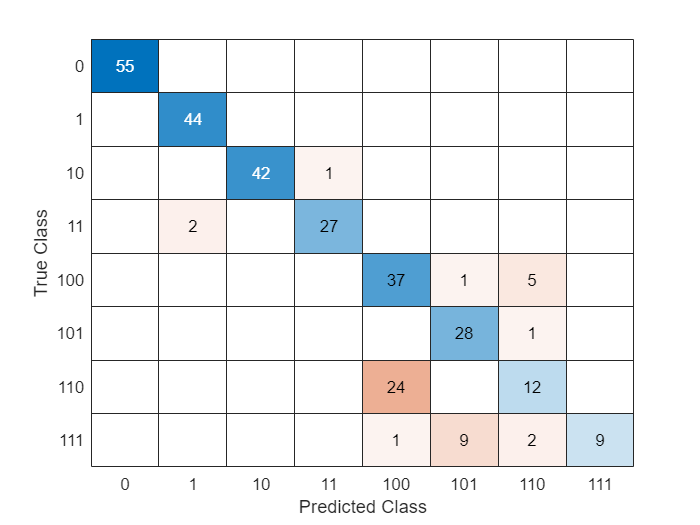

Training Error: 0.19143
Loss: 0.16654


evalModel(dataTest, mdlNB)

## Task 2

By default, the numeric predictors are modeled as normal (Gaussian) distributions, with estimated means and standard deviations. However, the assumption of normality may not always be appropriate. You can change the distribution using the `"DistributionNames"` property.

`nbModel` `=` `fitcnb``(``trainingData``,``...`

    `"ResponseVariable"``,``...`

    `"DistributionNames"``,``distName``)``;`

mdlNB = fitcnb(dataTrain, "faultCode", "DistributionNames", "kernel");

Evaluate model

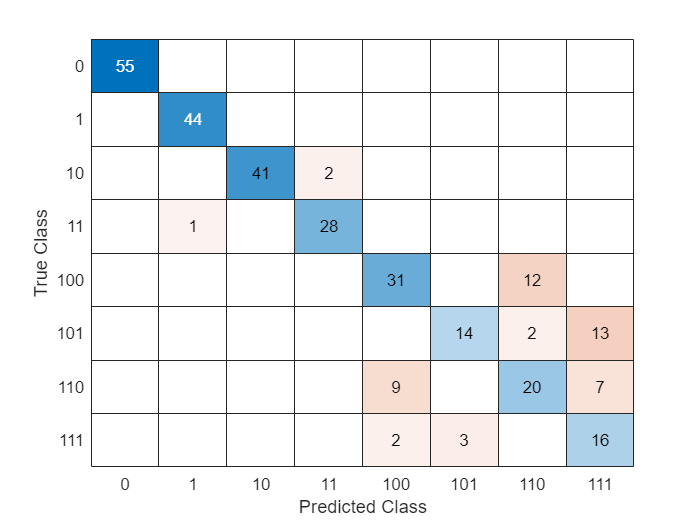

Training Error: 0.088571
Loss: 0.17699


evalModel(dataTest, mdlNB)

## Task 3

Sometimes you may want to use different distributions for different variables. In this case, you can set the `"DistributionNames"` property using an array of distribution names.

 `nbModel` `=` `fitcnb``(``trainingData``,``"Response"``,``...`

 `"DistributionNames"``,``[``"kernel"``,``"mvmn"``,``"mvmn"``])``;`

You can use the [repmat](https://www.mathworks.com/help/matlab/ref/repmat.html) function to create a string array with repeated values.

`d` `=` `repmat``(``"kernel"``,``1``,``2``)`

`d` `=` 

    `"kernel"`    `"kernel"`

dists = [repmat("normal", 1, 28), repmat("kernel", 1, 56)];
mdlNB = fitcnb(dataTrain, "faultCode", "DistributionNames", dists);

Evaluate model

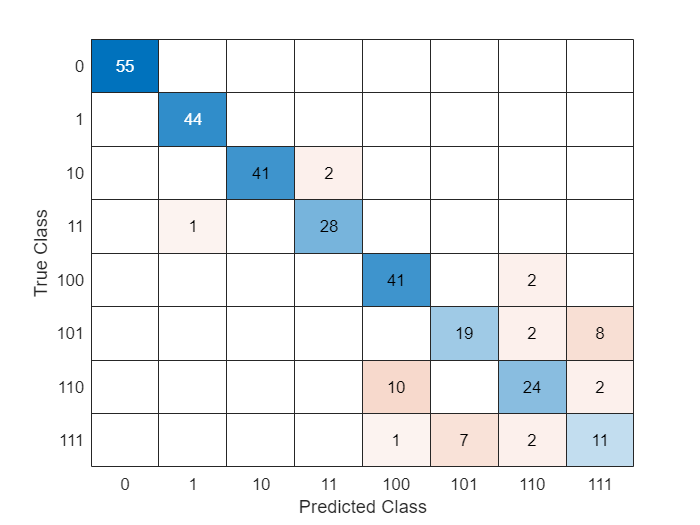

Training Error: 0.085714
Loss: 0.14316


evalModel(dataTest, mdlNB)

Do not edit. This function is used to evaluate a model by displaying the confusion chart, training error, and test loss.

function evalModel(dataTest, mdl)
    confusionchart(dataTest.faultCode, predict(mdl, dataTest))
    disp("Training Error: " + resubLoss(mdl))
    disp("Loss: " + loss(mdl, dataTest))
end